# Лабораторная работа №4

# Переходные процессы в цепях первого и второго порядка

## Цель  работы: получение навыков экспериментального  исследования переходных процессов в цепи с одним накопителем энергии (конденсатором) и с двумя накопителями  энергии.

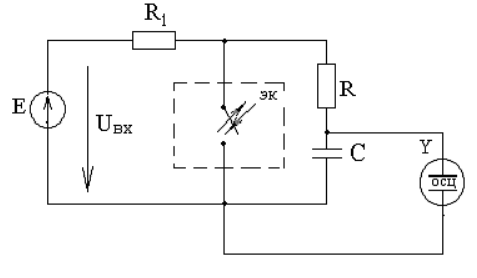

Расчет переходного процесса для цепи первого порядка:

U_0 = 10;
R1 = 300;
R = 300;
C = 5e-6;

До коммутации:

I_0 = 0

I_0 = 0

U_C_0 = U_0     %U_C до коммутации

U_C_0 = 10

после коммутации

при t=+inf:

syms I_1 I_2 I_3 U_C;
f1 = I_1-I_2-I_3==0;    %решение системы уравнений Киргоффа
f2 = R1*I_1==U_0;
f3 = R*I_3+U_C+R1*I_1==U_0;
f4 = I_3==0;
sol = solve(f1,f2,f3,f4);
U_C_pr = double(sol.U_C)    %U_C принужденная

U_C_pr = 0

при t=0

syms p;
p = double(solve(R*C*p+1==0))   %Корень характ. ур.

p = -666.6667

tau = -1/p

tau = 0.0015

delta_t = 4.6*tau

delta_t = 0.0069

syms A
U_C_sv = @(t) A.*exp(p.*t);   %Рассчет U_C свободная
U_C = @(t) U_C_pr + U_C_sv(t);  %Общее решение дифф. уравнения
A = solve(U_C(0)==U_C_0)    %Постоянная интегрирования

$$A = 10$$

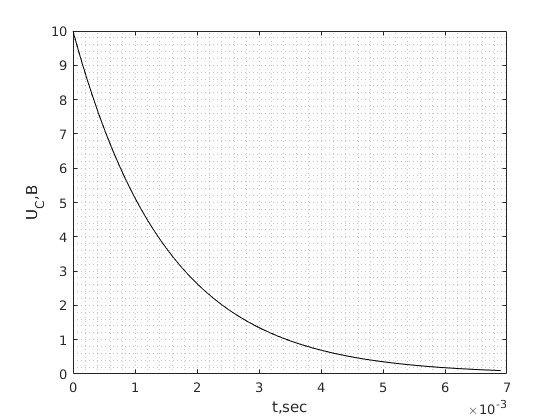

U_C_sv = @(t) A.*exp(p.*t);
U_C = @(t) U_C_pr + U_C_sv(t);  %Частное решение дифф. уравнения
plot(0:1e-5:delta_t,U_C(0:1e-5:delta_t),'k-')
grid minor
xlabel('t,sec')
ylabel('U_C,В')

Осцилограмма зависимости напряжения на конденсаторе от времени при практических измерениях:

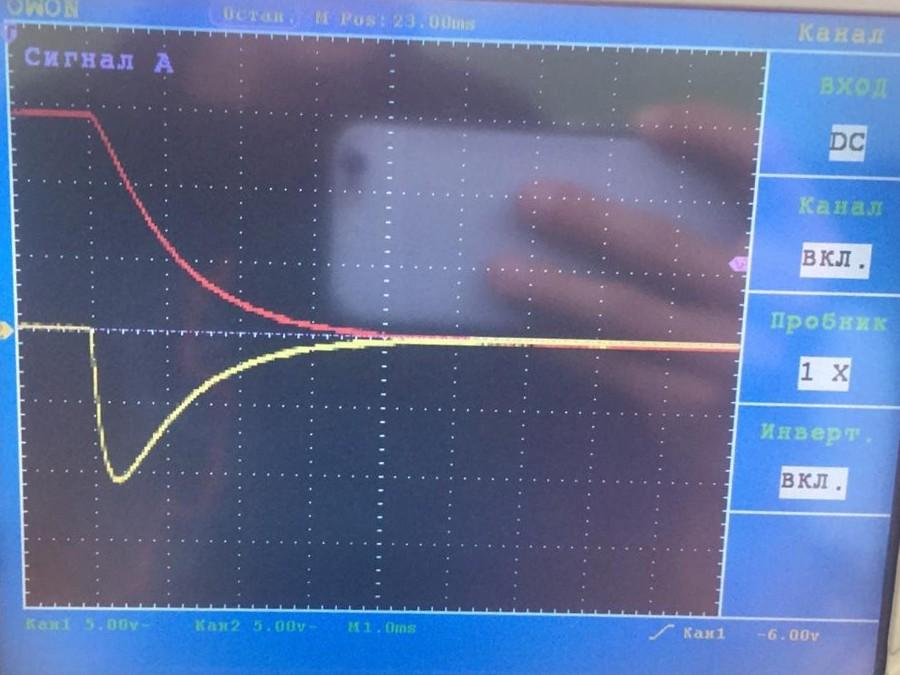

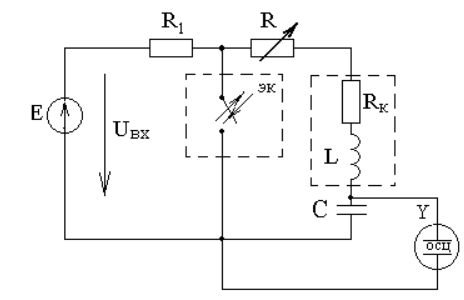

Расчёт переходного процесса для цепи второго порядка:

U_0 = 10;
R1 = 300;
R = 10;
C = 5e-6;
L = 30e-3;

До коммутации:

I_0 = 0     %I_L до коммутации

I_0 = 0

U_C_0 = U_0     %U_C до коммутации

U_C_0 = 10

после коммутации

при t=+inf:

syms I_1 I_2 I_3 U_C U_L;
f1 = I_1-I_2-I_3==0;    %решение системы уравнений Киргоффа
f2 = R1*I_1==U_0;
f3 = R*I_3+U_C+U_L+R1*I_1==U_0;
f4 = I_3==0;
f5 = U_L==0;
sol = solve(f1,f2,f3,f4,f5);
U_C_pr = double(sol.U_C)    %U_C принужденная

U_C_pr = 0

I_L_pr = double(sol.I_3)    %I_L принужденная

I_L_pr = 0

при t=0

syms p;
p = double(solve( (R1*(R+L*p+1/(C*p)))/(R1+R+L*p+1/(C*p)) ))   %Корень характ. ур.

p = 	1.0e+03 *

  -0.1667 - 2.5766i
  -0.1667 + 2.5766i


alpha = abs(real(p(1)));

alpha = 166.6667

omega = abs(imag(p(1)));

omega = 2.5766e+03

tau = 1/alpha

tau = 0.0060

delta_t = 4.6*tau

delta_t = 0.0276

syms A psi
U_C_sv = @(t) A.*exp(-alpha*t)*sin(omega*t+psi);
U_C_sv_diff = @(t) -alpha*A*exp(-alpha*t)*sin(omega*t+psi)+omega*A*exp(-alpha*t)*cos(omega*t+psi);

По закону о коммутации ток на катушке после коммутации остался таким-же как и до коммутации $I_L \left(0-\right)=I_L \left(0+\right)$, соответственно можно найти $\frac{\mathrm{d}}{\mathrm{d}t}U_C \left(t\right)$ по такой формуле: $I_C \left(t\right)=C\frac{\mathrm{d}}{\mathrm{d}t}U_C \left(t\right)=0$

f1 = U_C_0 == U_C_pr + U_C_sv(0) %частное решение дифф. ур.

$$f1 = 10=A\,\sin\left(\psi \right)$$

f2 = U_C_sv_diff(0) == 0

$$f2 = \frac{5666012421917359\,A\,\cos\left(\psi \right)}{2199023255552}-\frac{500\,A\,\sin\left(\psi \right)}{3}=0$$

sol = solve(f1,f2);

sol = struct with fields:
      A: [2×1 sym]
    psi: [2×1 sym]


A = double(sol.A)

A =    10.0209
  -10.0209


psi = double(sol.psi)

psi =     1.5062
   -1.6354


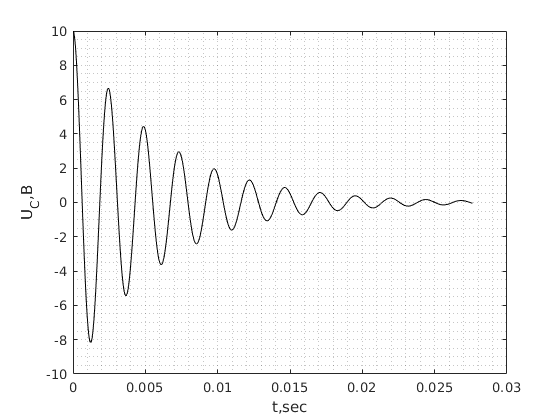


U_C_sv = @(t) A.*exp(-alpha.*t).*sin(omega.*t+psi);   %Рассчет U_C свободная
U_C = @(t) U_C_pr + U_C_sv(t);  %Частное решение дифф. уравнения
plot(0:1e-5:delta_t,U_C(0:1e-5:delta_t),'k-')
grid minor
xlabel('t,sec')
ylabel('U_C,В')

Осцилограмма зависимости напряжения на конденсаторе от времени при практических измерениях: